## Exo 1

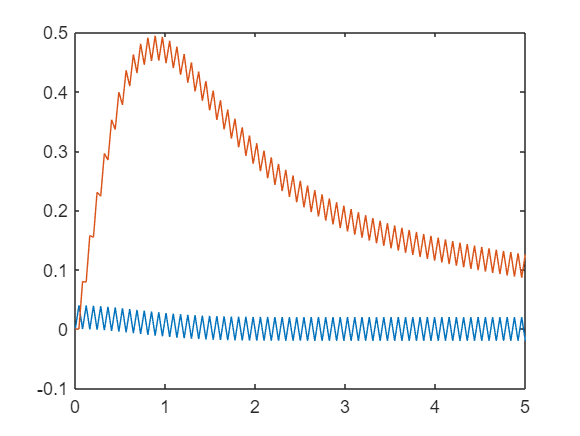

N1=125;N2=250;
h1=5/N1;h2=5/N2;
t1=linspace(0,5,N1);t2=linspace(0,5,N2);
X1=zeros(2,N1);X2=zeros(2,N2);

for i=2:N1
    X1(1,i)=X1(1,i-1)+h1*(-50*X1(1,i-1)+exp(-t1(i)^2));
    X1(2,i)=X1(2,i-1)+h1*(50*X1(1,i-1)-2*X1(2,i-1)^2);
end
plot(t1,X1(1,:),t1,X1(2,:))

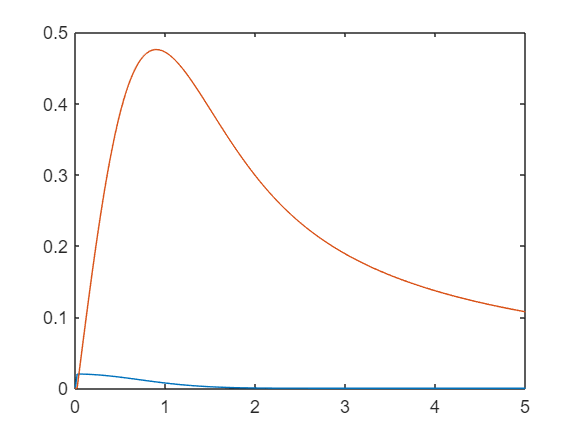




for i=2:N2
    X2(1,i)=X2(1,i-1)+h2*(-50*X2(1,i-1)+exp(-t2(i)^2));
    X2(2,i)=X2(2,i-1)+h2*(50*X2(1,i-1)-2*X2(2,i-1)^2);
end
plot(t2,X2(1,:),t2,X2(2,:))

X2(2,N2)

ans = 0.1075

0.10778

ans = 0.1078

Euler implicite

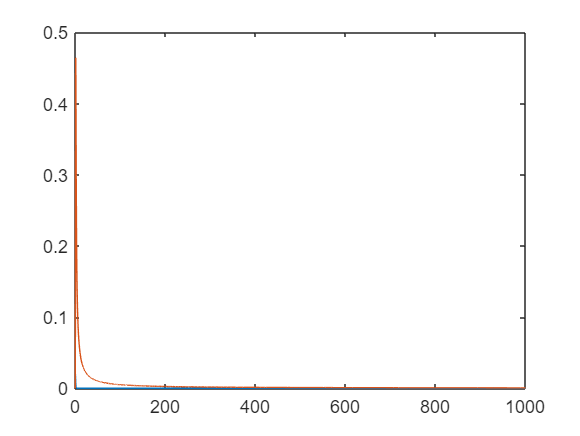

h3=0.05;
N3=1000/h3;
t3=linspace(0,1000,N3);
X3=zeros(2,N3);

for i=2:N3
    X3(1,i)=(X3(1,i-1)+h3*exp(-t3(i)^2))/(1+50*h3);
    X3(2,i)=(sqrt(1+8*h3*X3(2,i-1)+400*h3^2*X3(1,i-1))-1)/(4*h3);
end
plot(t3,X3(1,:),t3,X3(2,:))

X3(:,N3)

ans = 	1.0e+-3 *

         0
    0.5004
